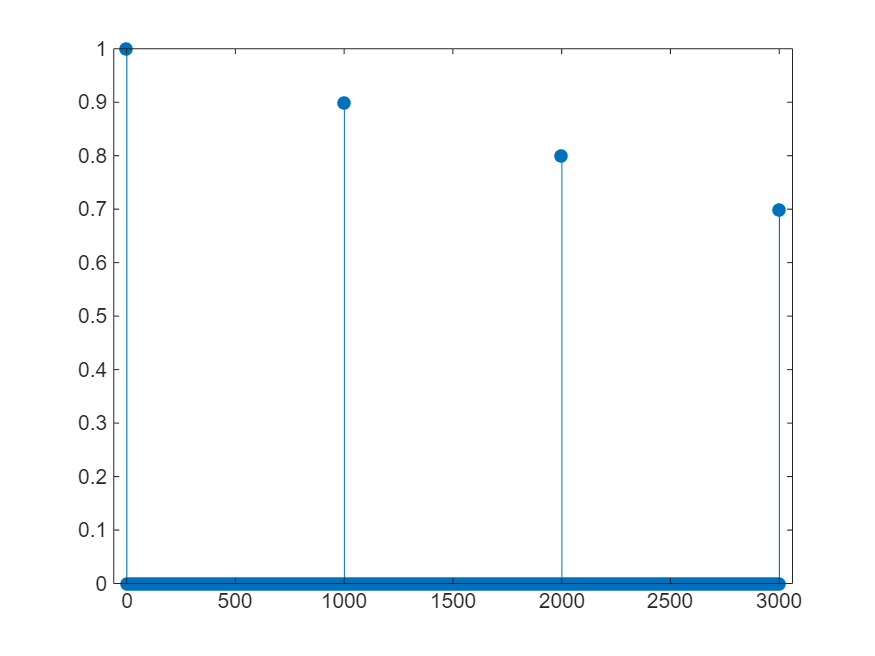

clear all;
close all;
clc;
[xn,fs] = audioread('sample_audio_file.wav');
% convert from stero to mono 
xn = mean(xn,2);
N_xn = length(xn);
% axis of drawing 
t = linspace(0, N_xn/fs ,N_xn);
% divided by fs or N ? 
xf = abs(fft(xn)) / N_xn;
%xf = xf(1:N/2);
f = linspace(0, fs ,N_xn);

hn = zeros(1,3001);
D = 1000 ;
hn(1) = 1 ; 
hn(1*D+1) = 0.9 ;
hn(2*D+1) = 0.8 ;
hn(3*D+1) = 0.7 ;

N_DFT = 8192; % N-DFT
n = linspace(1,length(hn),length(hn));
figure
stem(n,hn,"filled");

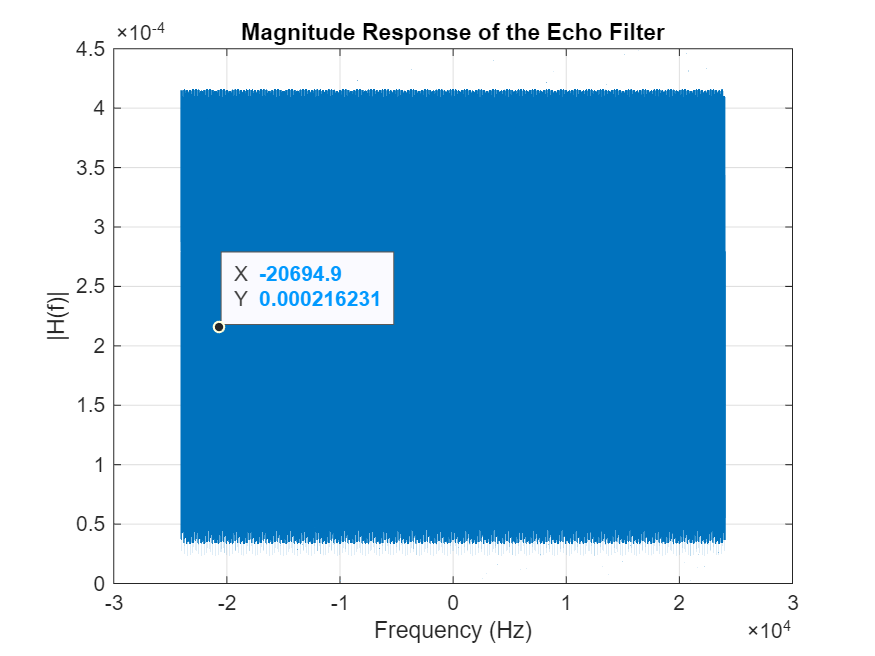

% we should implement the group delay !!!! 

% Magnitude and phase response of the filter in dB
% 1- get hn in freq domain 
Hf = fftshift( fft(hn, N_DFT) / N_DFT );
Hfmag = abs(Hf);
f = linspace(-fs/2, fs/2 ,N_DFT);
% YOU Neeed to plot in DB !!!! 
figure;
plot(f, Hfmag, 'LineWidth',1.2)
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude Response of the Echo Filter');
grid on;

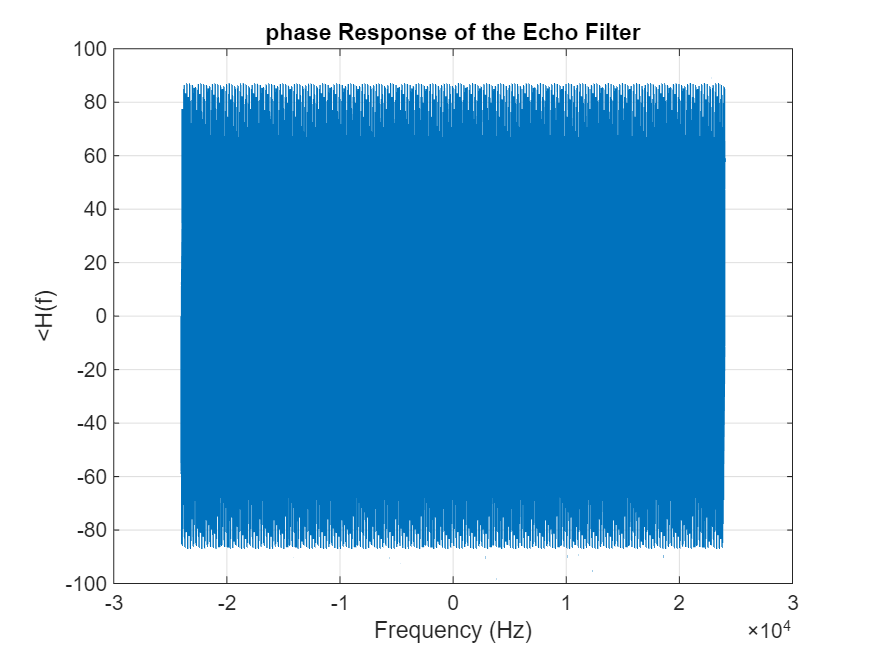

% phase plot 
Hfdegree = angle(Hf) * (180/pi) ; 
figure;
plot(f, Hfdegree, 'LineWidth',1.2)
xlabel('Frequency (Hz)');
ylabel('<H(f)');
title('phase Response of the Echo Filter');
grid on;

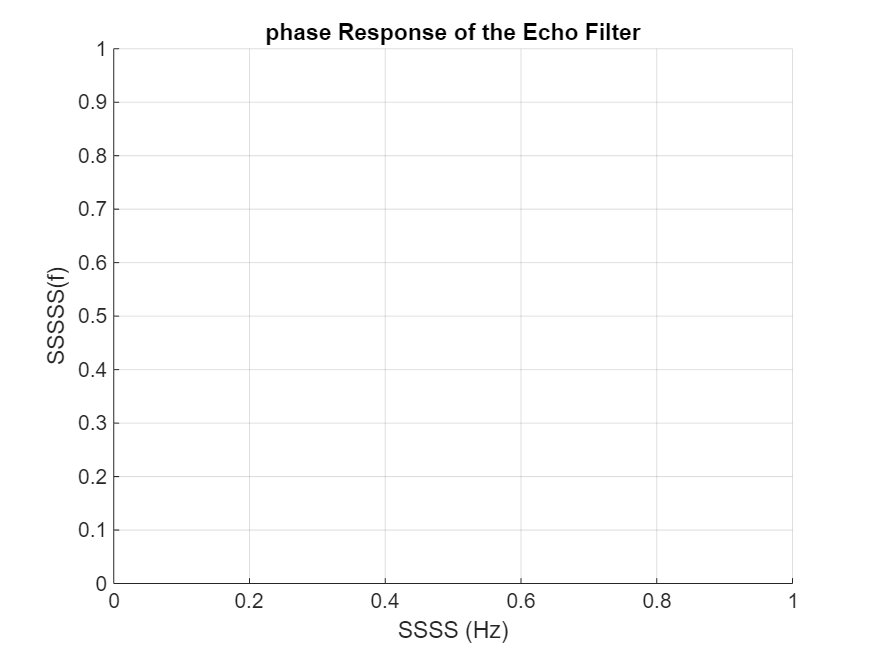

% P-Z plot 
figure 
%zplane(hn,1);
xlabel('SSSS (Hz)');
ylabel('SSSSS(f)');
title('phase Response of the Echo Filter');
grid on;

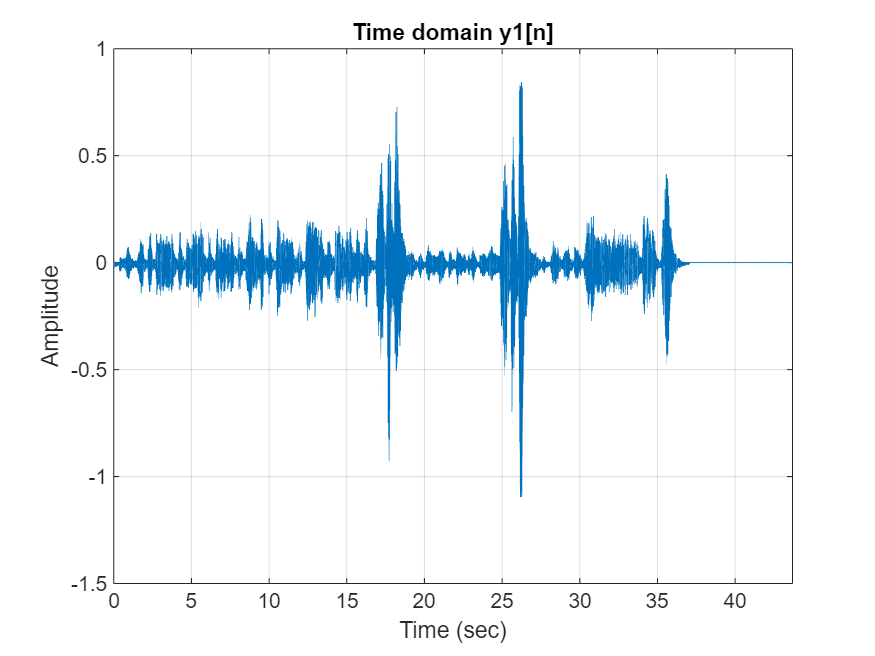

y1n = conv(hn,xn);
audio_echo = audioplayer(real(y1n), fs);
%playblocking(audio_echo);
figure
plot(t,y1n(1:N_xn))
grid on
title('Time domain y1[n]')
xlabel('Time (sec)')
ylabel('Amplitude')
xlim([0, N_xn/fs])

% MSE for Y1 
MSE1 = (1/(N_xn+1)) * sum((y1n(1:N_xn)-xn).^2)

MSE1 = 0.0019

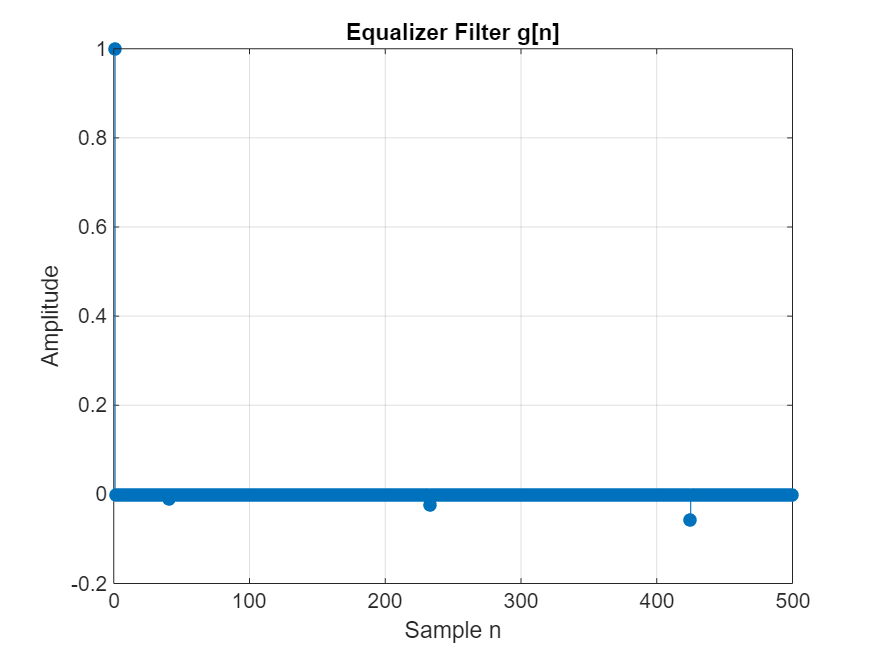

%N_DFT = ;

% Get frequency response of h[n]
Hf_eq = fft(hn, N_DFT);

% Design inverse filter with regularization
% epsilon prevents division by zero or very small numbers
Gf = 1 ./ (Hf_eq );

% Convert back to time domain
gn = real(ifft(Gf));

% Truncate to reasonable length (same as hn)
gn = gn(1:length(hn));

% Plot equalizer g[n]
figure;
stem(1:length(gn), gn, 'filled');
title('Equalizer Filter g[n]');
xlabel('Sample n');
ylabel('Amplitude');
grid on;
xlim([0 500]); % Show first 500 samples for clarity

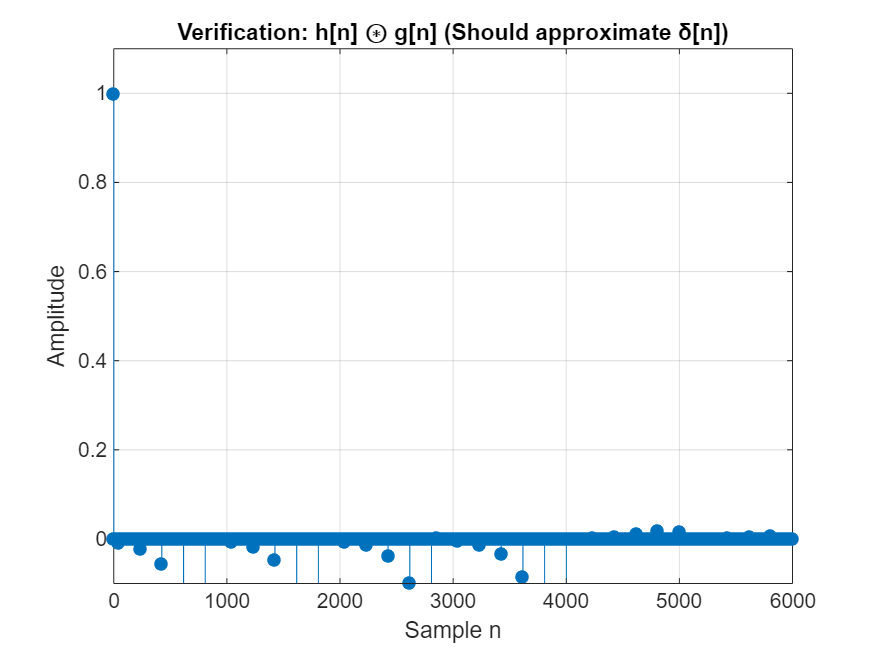

% Verify: h[n] * g[n] should approximate delta[n]
verification = conv(hn, gn);
figure;
stem(1:length(verification), verification, 'filled');
title('Verification: h[n] ⊛ g[n] (Should approximate δ[n])');
xlabel('Sample n');
ylabel('Amplitude');
grid on;
xlim([0 6000]);
% Zoom in on the peak
ylim([-0.1 1.1]);


% Find and display the peak location
[peak_val, peak_idx] = max(abs(verification));
fprintf('Peak of h[n]*g[n] at sample %d with value %.4f\n', peak_idx, peak_val);

Peak of h[n]*g[n] at sample 1 with value 1.0000


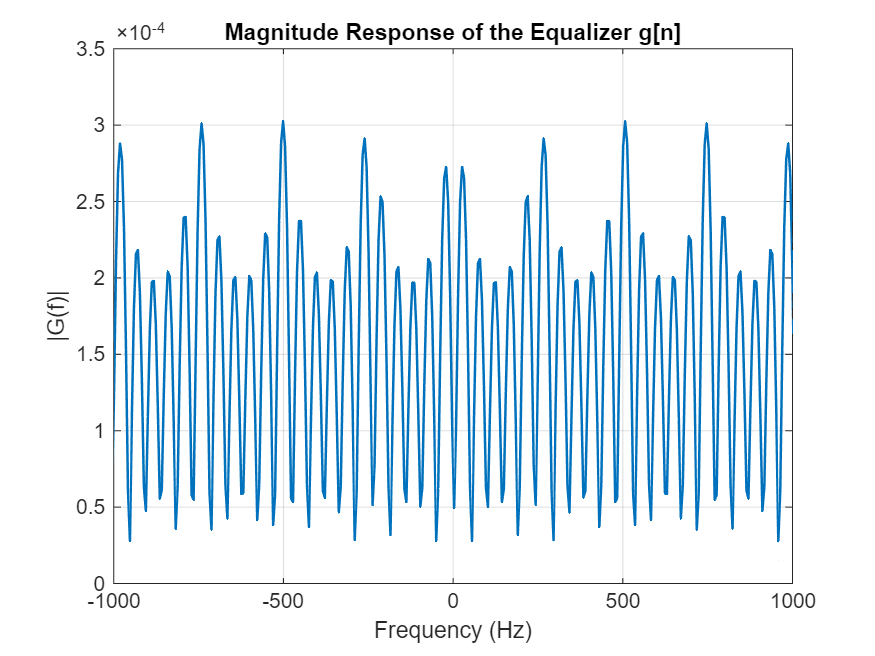


% Frequency response of equalizer
Gf_plot = fftshift(fft(gn, N_DFT) / N_DFT);
Gfmag = abs(Gf_plot);
f_plot = linspace(-fs/2, fs/2, N_DFT);

figure;
plot(f_plot, Gfmag, 'LineWidth', 1.2)
xlabel('Frequency (Hz)');
ylabel('|G(f)|');
title('Magnitude Response of the Equalizer g[n]');
grid on;
xlim([-1000,1000])

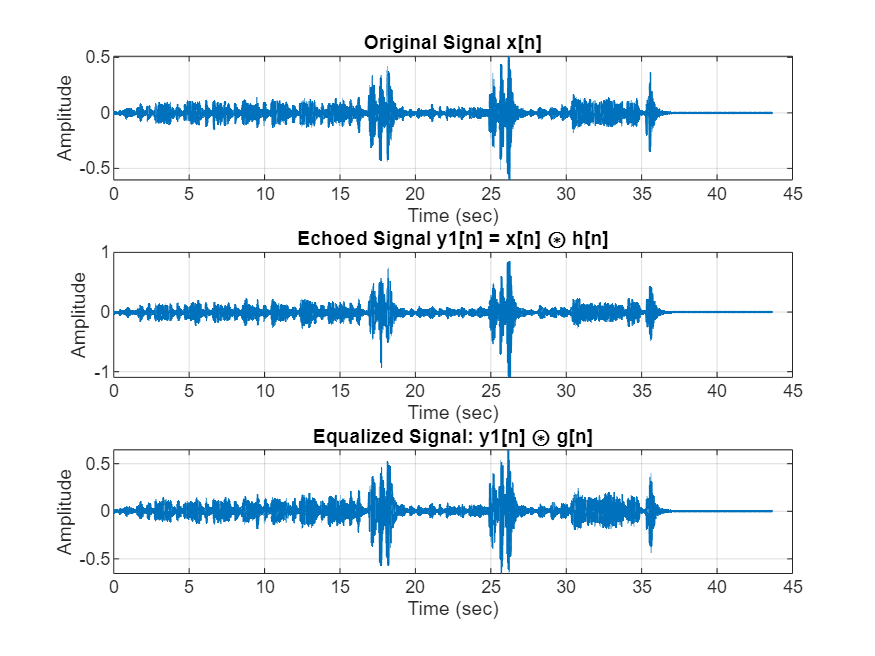


%% Apply equalizer to echoed signal
y1n_equalized = conv(y1n, gn);

% Truncate to original length
y1n_equalized = y1n_equalized(1:N_xn);

%% Comparison plots
figure;
subplot(3,1,1);
plot(t, xn, 'LineWidth', 1.2);
title('Original Signal x[n]');
xlabel('Time (sec)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, y1n(1:N_xn), 'LineWidth', 1.2);
title('Echoed Signal y1[n] = x[n] ⊛ h[n]');
xlabel('Time (sec)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t, y1n_equalized, 'LineWidth', 1.2);
title('Equalized Signal: y1[n] ⊛ g[n]');
xlabel('Time (sec)');
ylabel('Amplitude');
grid on;


 audio_equalized = audioplayer(real(y1n), fs);
 %playblocking(audio_equalized);
 MSE2 = (1/(N_xn+1)) * sum((y1n_equalized(1:N_xn)-xn).^2)

MSE2 = 6.6801e-04